# Parallel Simulation Processing, SLIP Controller

**Last modified: **August 18, 2022

**Authors: **Jack Butler

**Description: **This MATLAB live script unpacks the data from parallel simulation of the SLIP controller.

**Necessary Files:**

- `parsim_in_SLIP: `Input parameters to the most recent batch simulation of the SLIP controller

- `parsim_out_SLIP: `Output of the most recent batch simulation of the SLIP controller

### Load Simulation Results

The simulation results are usually pretty big files, so this might take some time!

clear; close all; clc;

%load the datasets
siminput = load("parsim_in_SLIP.mat").parameters;
simoutput = load("parsim_out_SLIP.mat").parallelout;

%figure out their dimensions
indims = size(siminput);
outdims = size(simoutput);

### Initialize Variables

tout = zeros(2,2);
speed = zeros(2,2);
rgain = zeros(2,2);
springconst = zeros(2,2);
z_pos = zeros(2,2);

### Unpack Simulation Results

Sorting the simulation data into input and output arrays.

%unpacking inputs
for i = indims(1):-1:1
    for j = indims(2):-1:1

        springconst(i,j) = siminput(i,j,1);
        rgain(i,j) = siminput(i,j,2);

    end
end

%unpacking outputs
for i = outdims(1):-1:1
    for j = outdims(2):-1:1
    
        tout(i,j) = max(simoutput(i,j).tout);
        speed(i,j) = max(simoutput(i,j).speed);
        z_pos(i,j) = max(simoutput(i,j).hop_height);
        loopchecksmeas1(i,j) = std(simoutput(i,j).loopchecks(1,1,:))/mean(simoutput(i,j).loopchecks(1,1,:));
        loopchecksmeas2(i,j) = std(simoutput(i,j).loopchecks(1,2,:))/mean(simoutput(i,j).loopchecks(1,1,:));

    end
end

%reshaping unpacked stuff into 1xn matrices
tout = reshape(tout,[],1);
rgain = reshape(rgain,[],1,1);
springconst = reshape(springconst,[],1);
speed = reshape(speed,[],1);
z_pos = reshape(z_pos,[],1);
loopchecksmeas1 = reshape(loopchecksmeas1,[],1);
loopchecksmeas2 = reshape(loopchecksmeas2,[],1);

### Success/Fail Detection

Sorts the array results into successes and failures.

%initializing variables
success_v_fail = zeros(length(tout),1);
successes = zeros(length(tout),1); % contains the indices of successful runs

% success and failure detection
for i = length(tout):-1:1
    if(tout(i) == 4)
        success_v_fail(i) = 1;
        successes(i) = i;
    else
        success_v_fail(i) = 0;
    end
end

%removing the zeros from the successes array
successes = nonzeros(successes);

%making arrays of successful parameters
for i = length(successes):-1:1

    successful_jumps(i) = z_pos(successes(i));
    successful_speeds(i) = speed(successes(i));
    successful_rgains(i) = rgain(successes(i));
    successful_springconsts(i) = springconst(successes(i));

end

### Plot the Data

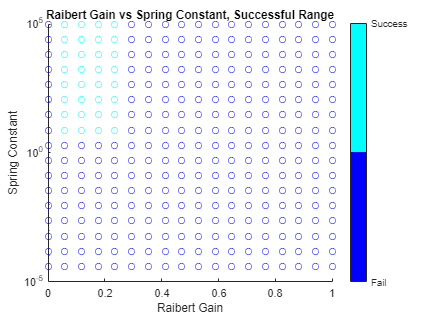

%making a scatter plot to find successful ranges easier
figure
scatter(rgain,springconst,[],success_v_fail)
colormap(jet(2))
colorbar('Ticks',[0,1],'TickLabels',{'Fail','Success'})
xlabel("Raibert Gain")
ylabel("Spring Constant")
set(gca,"YScale","log")
title("Raibert Gain vs Spring Constant, Successful Range")
hold off

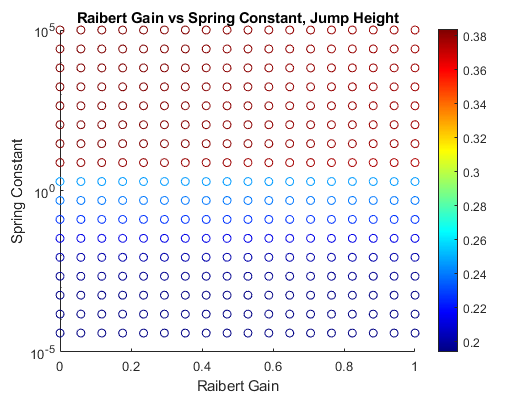


% showing relations between parameters and max jump height
figure
scatter(rgain,springconst,[],z_pos)
colormap(jet)
colorbar
xlabel("Raibert Gain")
ylabel("Spring Constant")
set(gca,"YScale","log")
title("Raibert Gain vs Spring Constant, Jump Height")
hold off

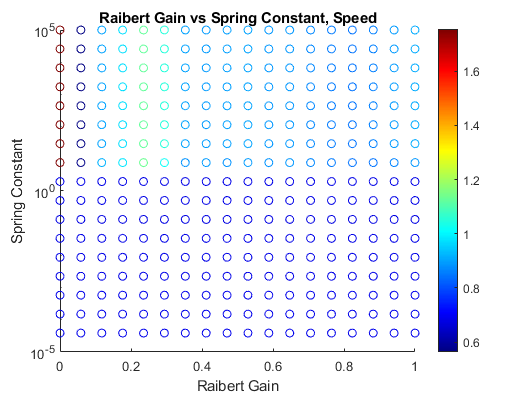


% showing relations between parameters and max speed
figure
scatter(rgain,springconst,[],speed)
colormap(jet)
colorbar
xlabel("Raibert Gain")
ylabel("Spring Constant")
set(gca,"YScale","log")
title("Raibert Gain vs Spring Constant, Speed")
hold off